This gives the disturbance test


$$P=\frac{2s+10}{s^2 +2s+10}$$


num = [2,10];
denum = [1,2,20];
Plant = tf(num,denum);
Q2 = TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


[~,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);

谱分解无明显误差


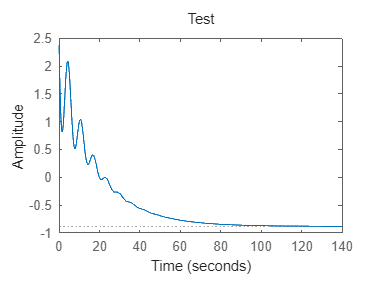

controllerSys = ss([C1,C2]);
plantSys = ss(Plant);
T = (Plant*C1)/(1+Plant*C2);
gain = 1/dcgain(T);
T = gain * T;
T_diy = Plant/(1+C2*Plant);